[min, max]=fminmax(@(t) t.^2 + 3, 0, 2)

min = 3

max = 7

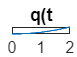


fplot(@(t) t.^2 + 3, [0,2]), title('q(t')

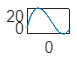

ans = 43.8999


p = @(x) 2*x.^3 - 2*x.^2 - 18*x +18;

frange(p, -3, 3)

function [fmin,fmax] = fminmax(f,a,b)
    x = linspace(a,b,10000);
    y = f(x);
    fmin = min(y);
    fmax = max(y);
end


function r = frange(f, a, b)
   x = linspace(a, b, 1e4);
   y = f(x);
   r = max(y) - min(y);

   fplot(f, [a, b])
end